%unzip('ResizedDataset.zip');

Load the image

imds = imageDatastore('C:\Users\Shreyas Desai\Desktop\test\ResizedDataset','IncludeSubfolders',true,'LabelSource','foldernames');

Count

tbl = countEachLabel(imds)

tbl = 4×2 table
       Label       Count
    ___________    _____

    Anime           100 
    Comedy          100 
    Horror           99 
    Science-fic      93 


Step 1

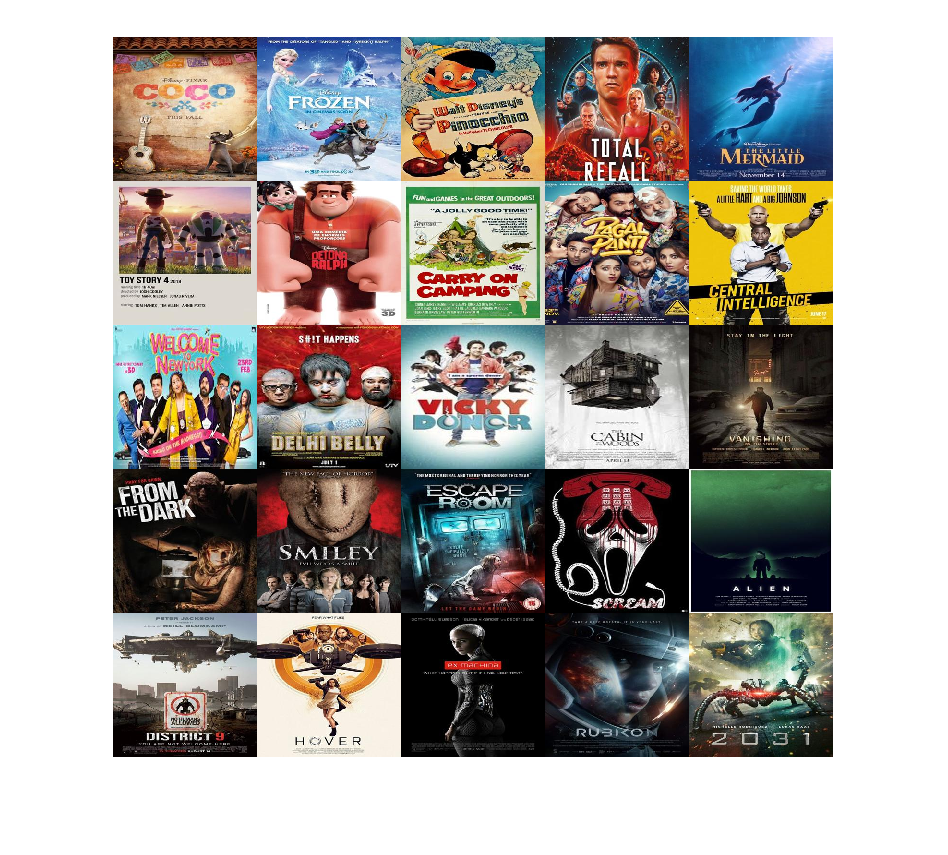

figure
montage(imds.Files(1:16:end))

Step 2

[trainingSet, validationSet] = splitEachLabel(imds, 0.8, 'randomize');

Step 3

bag = bagOfFeatures(trainingSet);

Creating Bag-Of-Features.
-------------------------
* Image category 1: Anime
* Image category 2: Comedy
* Image category 3: Horror
* Image category 4: Science-fic
* Selecting feature point locations using the Grid method.
* Extracting SURF features from the selected feature point locations.
** The GridStep is [8 8] and the BlockWidth is [32 64 96 128].

* Extracting features from 313 images...done. Extracted 1807888 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 4 has the least number of strongest features: 341939.
** Using the strongest 341939 features from each of the other image categories.

* Using K-Means clustering to create a 500 word visual vocabulary.
* Number of features          : 1367756
* Number of clusters (K)      : 500

* Initializing cluster centers...100.00%.
* Clustering...completed 14/100 iterations (~5.53 seconds/iteration)...conv

Step 4

img = readimage(imds, 1);
featureVector = encode(bag, img);

Step 5

% Plot the histogram of visual word occurrences
figure
bar(featureVector)
title('Visual word occurrences')
xlabel('Visual word index')
ylabel('Frequency of occurrence')

Step 6

categoryClassifier = trainImageCategoryClassifier(trainingSet, bag);

Training an image category classifier for 4 categories.
--------------------------------------------------------
* Category 1: Anime
* Category 2: Comedy
* Category 3: Horror
* Category 4: Science-fic

* Encoding features for 313 images...done.

* Finished training the category classifier. Use evaluate to test the classifier on a test set.



Step 7

confMatrix = evaluate(categoryClassifier, trainingSet);

Evaluating image category classifier for 4 categories.
-------------------------------------------------------

* Category 1: Anime
* Category 2: Comedy
* Category 3: Horror
* Category 4: Science-fic

* Evaluating 313 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                                PREDICTED
KNOWN          | Anime   Comedy   Horror   Science-fic   
---------------------------------------------------------
Anime          | 0.71    0.15     0.07     0.06          
Comedy         | 0.04    0.90     0.05     0.01          
Horror         | 0.06    0.05     0.84     0.05          
Science-fic    | 0.04    0.07     0.22     0.68          

* Average Accuracy is 0.78.



Step 8

confMatrix = evaluate(categoryClassifier, validationSet);

Evaluating image category classifier for 4 categories.
-------------------------------------------------------

* Category 1: Anime
* Category 2: Comedy
* Category 3: Horror
* Category 4: Science-fic

* Evaluating 79 images...done.

* Finished evaluating all the test sets.

* The confusion matrix for this test set is:


                                PREDICTED
KNOWN          | Anime   Comedy   Horror   Science-fic   
---------------------------------------------------------
Anime          | 0.20    0.50     0.25     0.05          
Comedy         | 0.20    0.80     0.00     0.00          
Horror         | 0.20    0.05     0.70     0.05          
Science-fic    | 0.21    0.11     0.21     0.47          

* Average Accuracy is 0.54.



Step 9

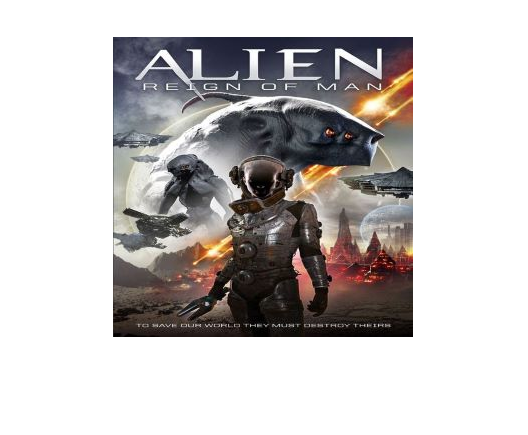

img = imread(fullfile('C:\Users\Shreyas Desai\Desktop','test','alien1.jpeg'));
figure
imshow(img)

Step 10

[labelIdx, scores] = predict(categoryClassifier, img);

Step 11

% Display the string label
x = categoryClassifier.Labels(labelIdx)

x = 1×1 cell array
    {'Science-fic'}


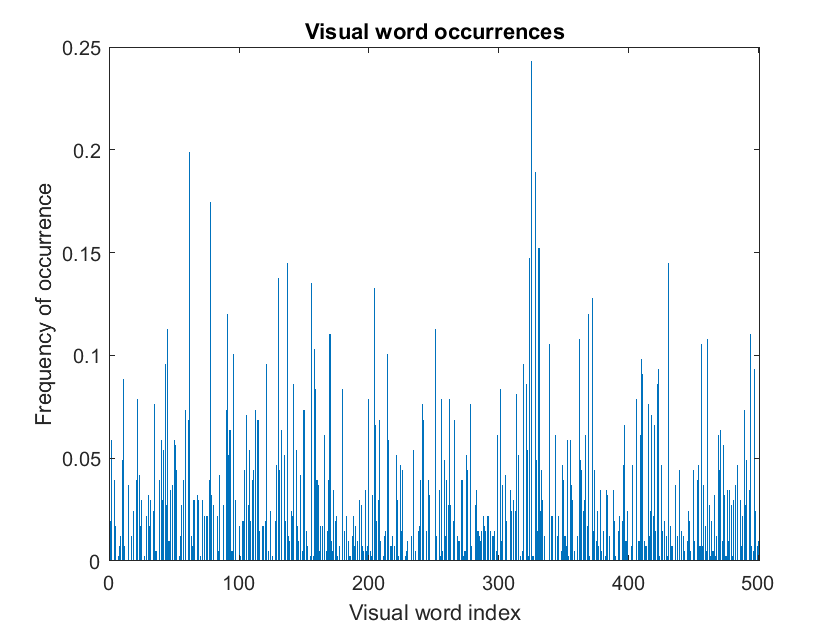

folder = 'C:\Users\Shreyas Desai\Desktop\test\ResizedDataset\Science-fic'

fileList = 93×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


randomIndex = 85

fullFileName = 'C:\Users\Shreyas Desai\Desktop\test\ResizedDataset\Science-fic\tron_resized.jpg'

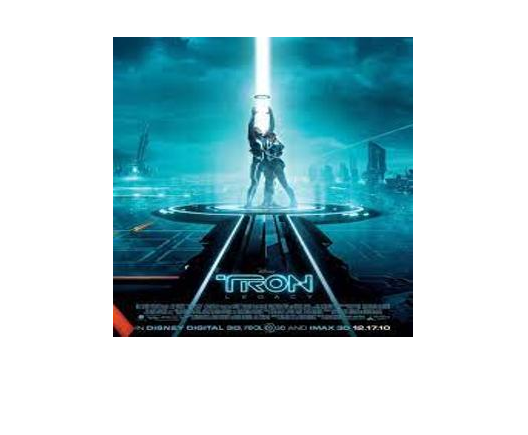

a = {'Science-fic'};
tf = isequal(x,a);


if tf==1
    folder = 'C:\Users\Shreyas Desai\Desktop\test\ResizedDataset\Science-fic'
fileList = dir(fullfile(folder, '/*.jpg'))
randomIndex = randi(length(fileList), 1, 1) % Get random number.
fullFileName = fullfile(folder, fileList(randomIndex).name)
img = imshow(fullFileName);
end